addpath ..\general-robotics-toolbox-master\

kin = define_sawyer();

kin_E = kin;
kin_E.joint_type = [0 0 0];

kin_W = kin;
kin_W.joint_type = [0 0 0 0 0];

kin_2 = kin;
kin_2.joint_type = [0];

%q = rand([7 1])*2*pi - pi
%q = zeros([7 1])

[R_7,p] = fwdkin(kin, q)

R_7 =    -0.9980    0.0171    0.0605
    0.0628    0.2492    0.9664
    0.0015    0.9683   -0.2497


p =    -0.1084
   -0.4630
   -0.1103


R = R_7*kin.RT

R =    -0.0063   -0.0625   -0.9980
   -0.0776   -0.9950    0.0628
   -0.9970    0.0778    0.0015



p_S = kin.P(:,1);

[~,p_E] = fwdkin(kin_E, q)

p_E =     0.3167
   -0.1666
   -0.0776


[~,p_W] = fwdkin(kin_W, q)

p_W =     0.0259
   -0.4715
   -0.1105



[~,p_2] = fwdkin(kin_2, q)

p_2 =     0.2076
   -0.0224
    0.3170



psi_conv = conv_sew(p_S, p_E, p_W, [0;0;1])

psi_conv = -2.0743

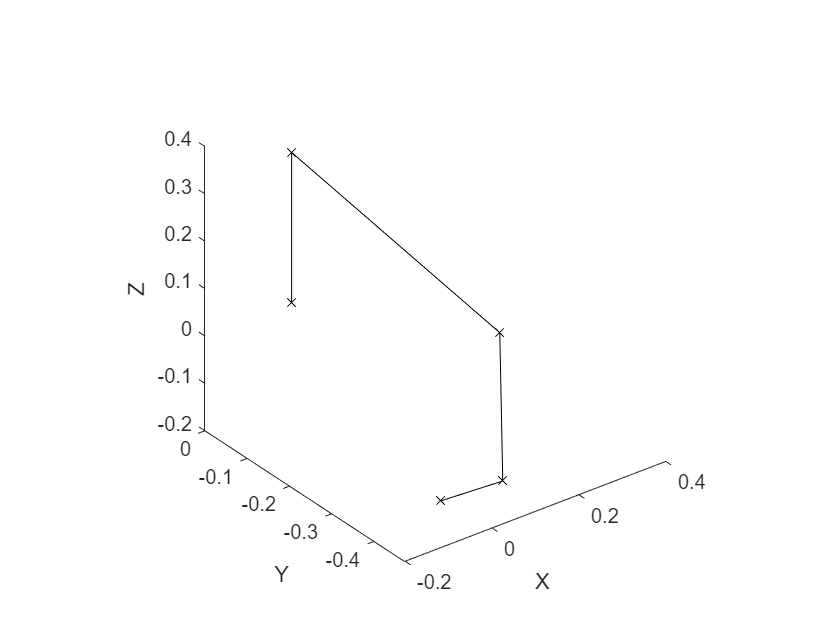



zv = [0;0;0];
kin_mat = [zv p_S p_E p_W p];
plot3(kin_mat(1,:), kin_mat(2,:), kin_mat(3,:), '-xk')
axis square
xlabel("X")
ylabel("Y")
zlabel("Z")


% wrist angle is measured from line from wrist to shoulder
% X axis: shoulder - wrist
% Y axis: direction of SEW half-plane

WA_X = vec_normalize(p_S - p_W);
P_WE = p_E - p_W;
WA_Y = vec_normalize(P_WE - WA_X*WA_X'*P_WE);

WA = atan2(WA_Y'*P_WE, WA_X'*P_WE)

WA = 0.9785


% [alignment, q_solns] = alignment_given_wrist_angle(WA,kin,R,p,psi_conv,[0;0;1])
% 
% q


%WA_guesses = linspace(0, 2*pi, 1000);
WA_guesses = linspace(0.3,1.1, 2000);
max_alignments = NaN(size(WA_guesses));
alignment_mat = NaN([length(WA_guesses) 16]);
for i = 1:length(WA_guesses)
    WA_guess = WA_guesses(i);
    [alignment_vec, ~] = alignment_given_wrist_angle(WA_guess,kin,R,p,psi_conv,[0;0;1]);
    if ~isempty(alignment_vec)
        max_alignments(i) = max(alignment_vec);
        alignment_mat(i,1:length(alignment_vec)) = alignment_vec;
    end
end

no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones


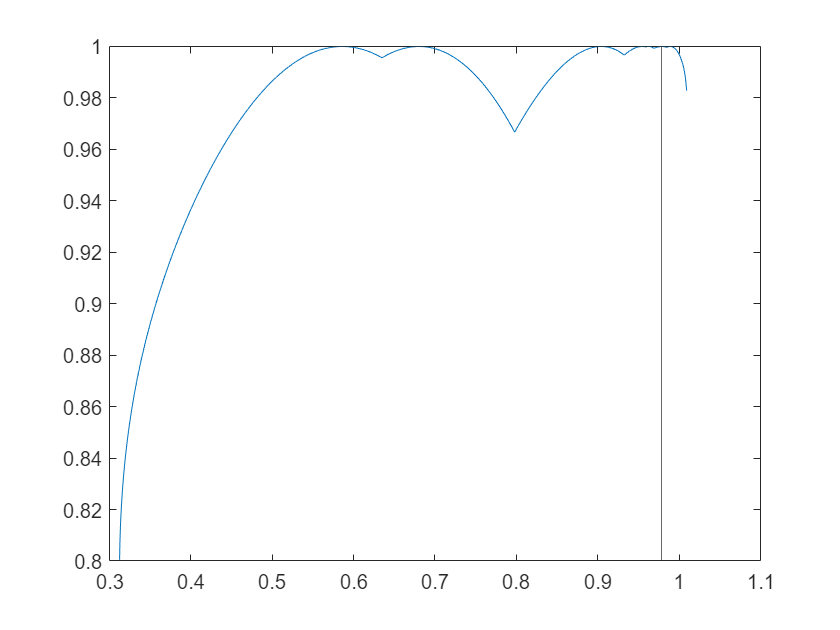


plot(WA_guesses, max_alignments);
yline(1);
xline(WA);

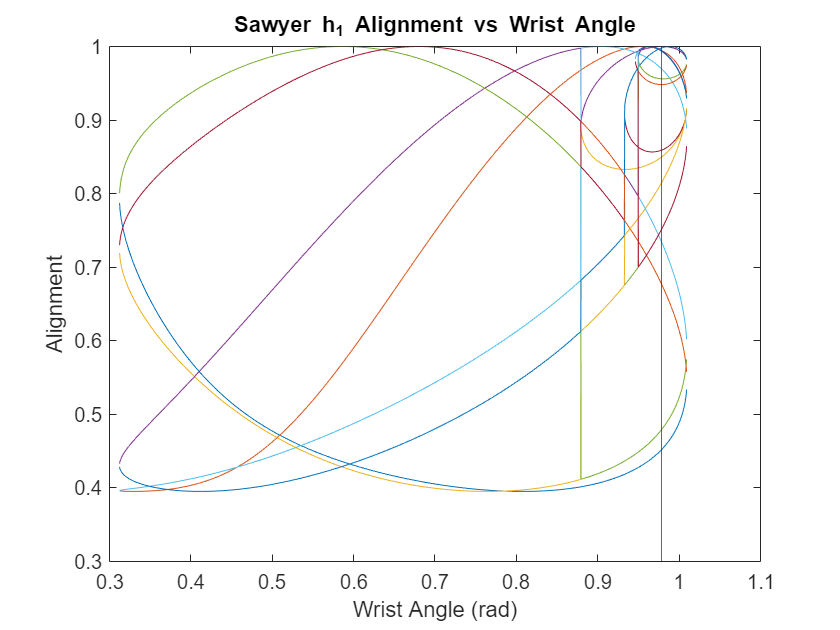


plot(WA_guesses, alignment_mat)
yline(1);
xline(WA);
xlabel("Wrist Angle (rad)")
ylabel("Alignment")
title("Sawyer h_1 Alignment vs Wrist Angle")

%xlim([0.3 1.1])


ans = 1.0e-06 *

    0.0057    0.0117    0.0266    0.0581    0.1368    0.1510    0.1859    0.1874    0.2747    0.4222


%ALIGNMENT_THRESH = 1-0.15e-6
ALIGNMENT_THRESH = 1-5e-3

ALIGNMENT_THRESH = 0.9950

%ALIGNMENT_THRESH = sorted_alignments(9)
%WA_angles = WA_guesses(max_alignments > ALIGNMENT_THRESH)
[max_align_i, ind_max_align_i] = max(alignment_mat)

max_align_i =     0.7871    1.0000    0.9123    1.0000    1.0000    1.0000    1.0000    1.0000    0.8979    0.9162    1.0000    0.9818    0.9932    0.9795    1.0000    0.9744


ind_max_align_i =           32        1637        1773        1696         716        1511         951        1722        1449        1773        1660        1625        1624        1616        1655        1773



WA_angles = [];
alignment_mins = [];
for i = 1:16
    if max_align_i(i) > ALIGNMENT_THRESH
        WA_angles = [WA_angles WA_guesses(ind_max_align_i(i))];
        alignment_mins = [alignment_mins max_align_i(i)];
    end
end
WA_angles

WA_angles =     0.9547    0.9783    0.5861    0.9043    0.6802    0.9887    0.9639    0.9619


alignment_mins

alignment_mins =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


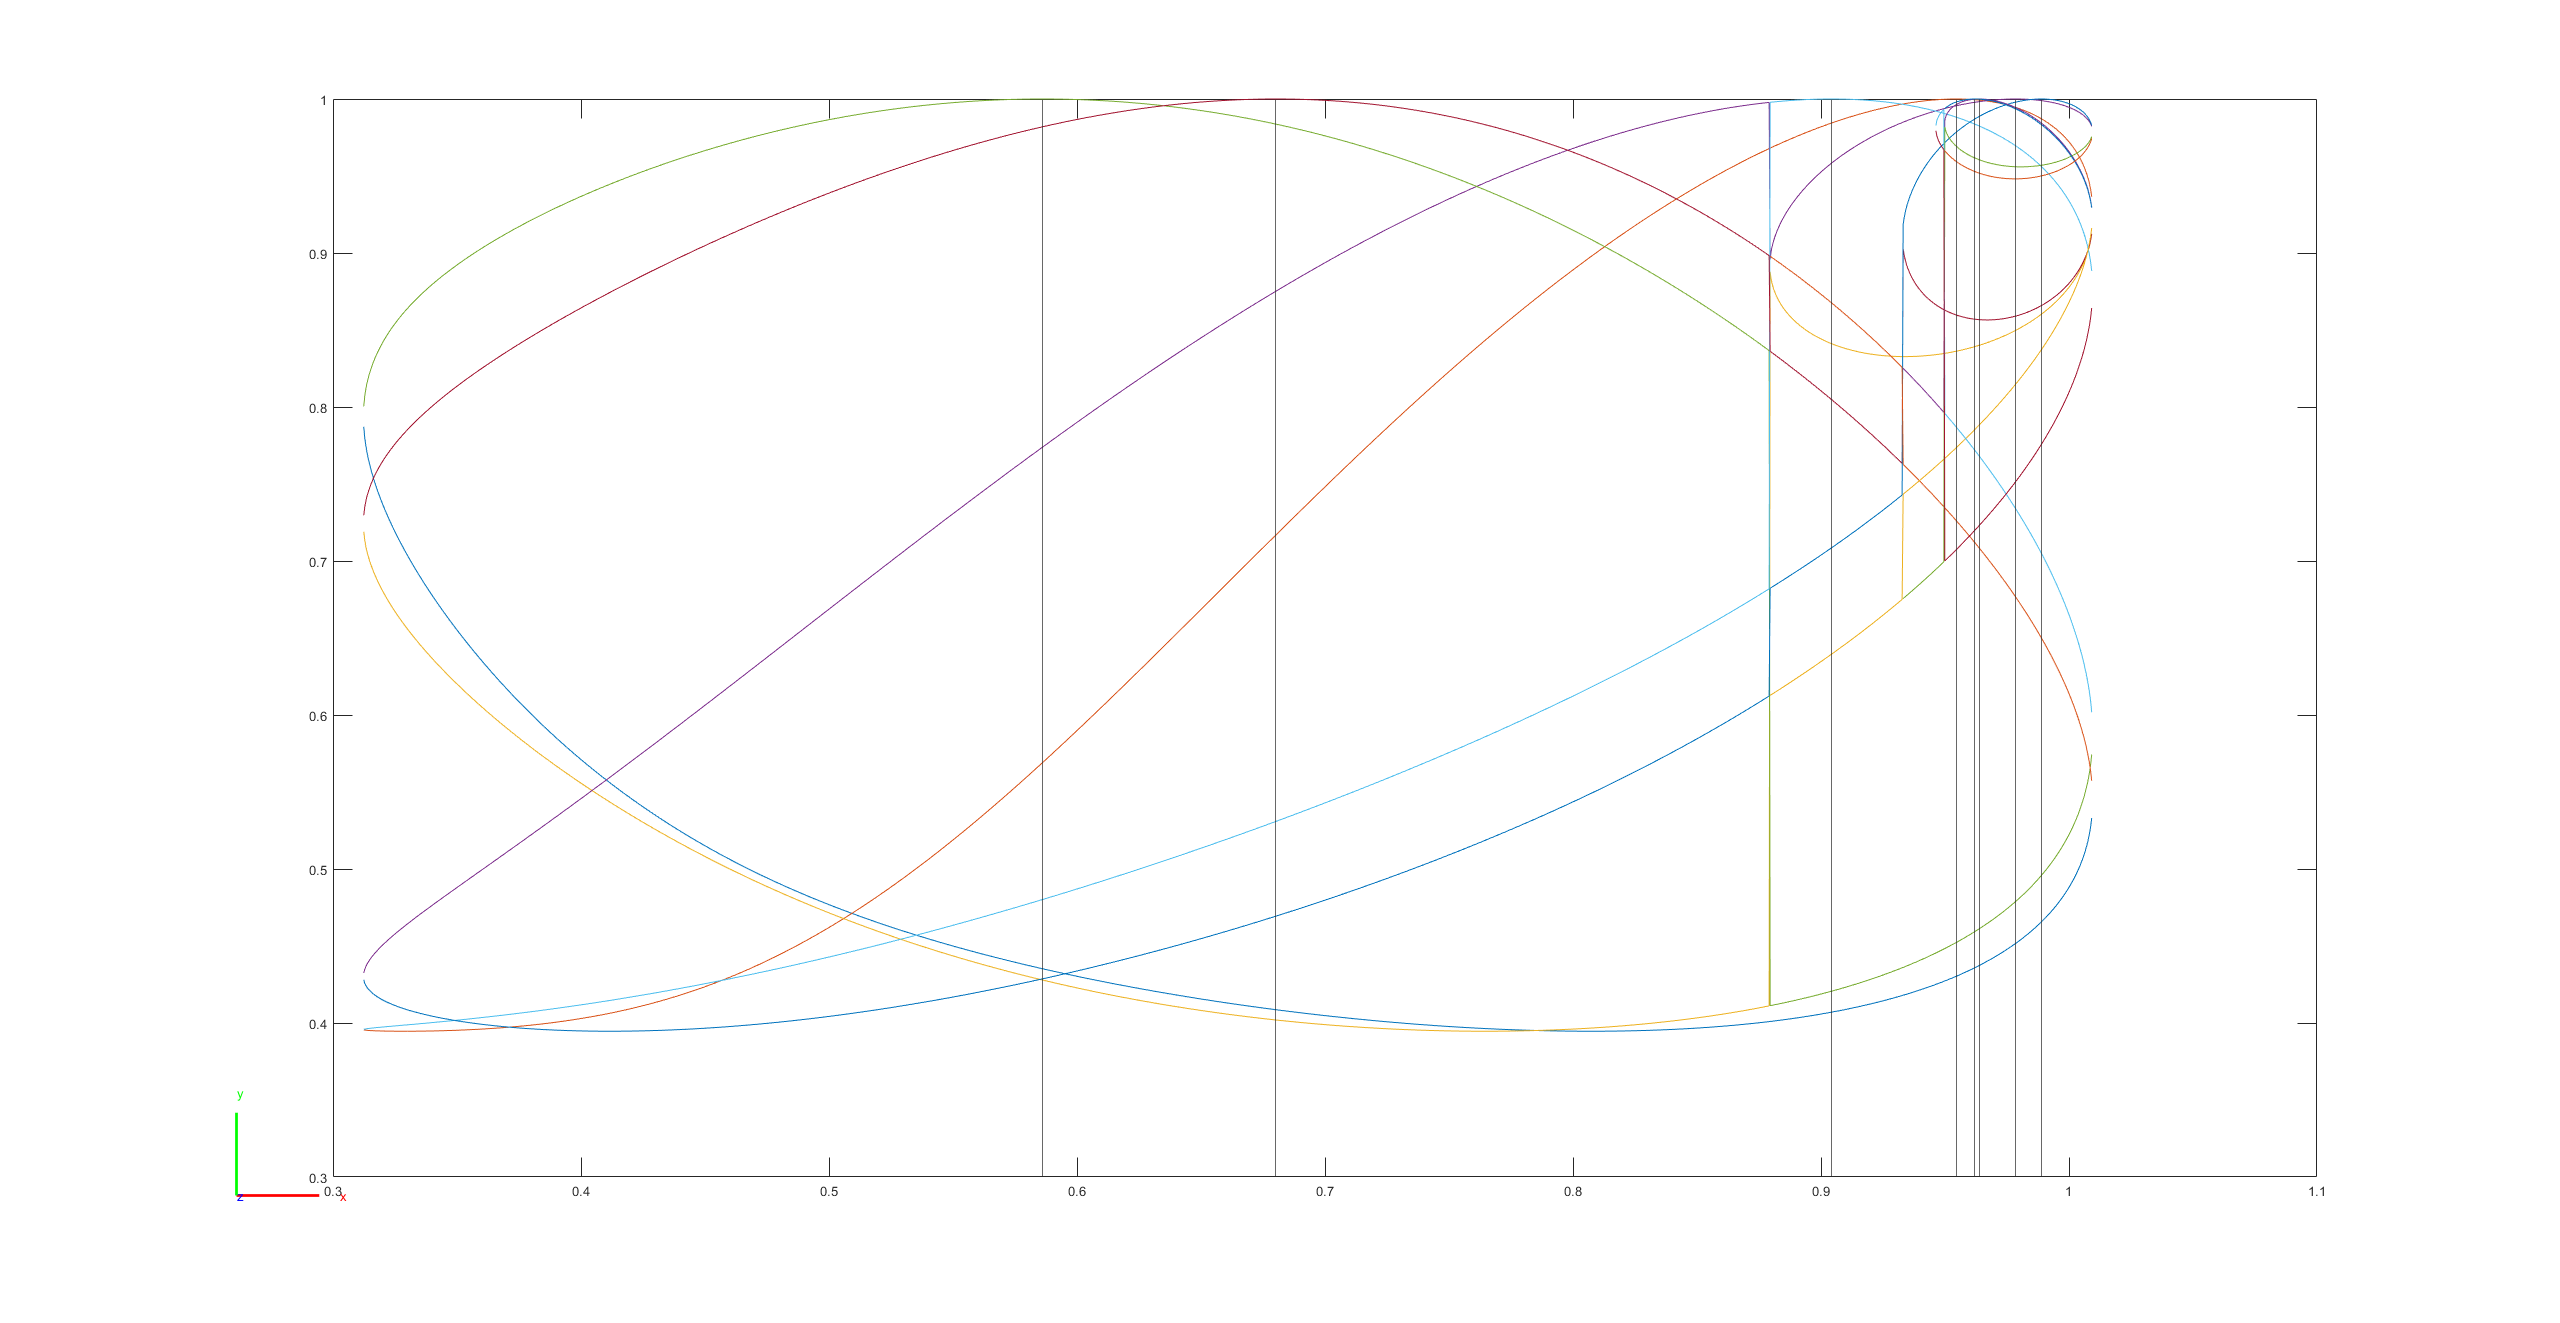


plot(WA_guesses, alignment_mat)
for ang = WA_angles
    xline(ang);
end


solutions = [];

for i = 1:length(WA_angles)
    WA_i = WA_angles(i)
    [alignment_vec, soln_mat] = alignment_given_wrist_angle(WA_i,kin,R,p,psi_conv,[0;0;1]);
    solutions = [solutions soln_mat(:,alignment_vec>alignment_mins(i)-1e-6)];
end

WA_i = 0.9547

WA_i = 0.9783

WA_i = 0.5861

no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones


WA_i = 0.9043

no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones


WA_i = 0.6802

no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones
no solution - no intersection found between cones


WA_i = 0.9887

WA_i = 0.9639

WA_i = 0.9619


solutions

solutions =    -1.1488   -1.2789    2.9226   -0.9369   -3.0528   -1.3510   -2.1141   -2.1241
    0.7090    1.5376    2.7172    0.6459    2.7544    1.5570    1.9544    1.9664
    1.7190   -1.9543   -0.7994    1.3152   -1.3186   -2.0810   -2.8369   -2.8220
   -1.1075    1.1731   -1.5870   -1.5498   -2.1810    1.8128    1.5399    2.1823
    0.2277   -1.9888    0.2010   -2.3199   -2.6708    1.7964   -1.8364    1.9059
   -0.8448   -0.8264   -1.1496    0.8846    1.0693    0.8184   -0.8376    0.8392
    0.8047    0.7894    1.0130   -3.1350   -2.9192    3.0507    0.7988    3.0828



for q_i = solutions
    [R_7_i,p_i] = fwdkin(kin, q_i);
    [~,p_E_i] = fwdkin(kin_E, q_i);
    [~,p_W_i] = fwdkin(kin_W, q_i);
    
    psi_conv_i = conv_sew(p_S, p_E_i, p_W_i, [0;0;1]);
    [norm(R_7_i - R_7) norm(p_i - p) norm(psi_conv_i - psi_conv)]
end

ans = 1.0e-03 *

    0.6194    0.2861    0.0782


ans = 1.0e-03 *

    0.9989    0.4715    0.1720


ans = 1.0e-03 *

    0.2786    0.1294    0.0223


ans = 1.0e-03 *

    0.1933    0.0852    0.0105


ans = 1.0e-03 *

    0.4189    0.1919    0.0999


ans =     0.0013    0.0006    0.0003


ans = 1.0e-03 *

    0.9507    0.4580    0.3791


ans =     0.0024    0.0012    0.0010


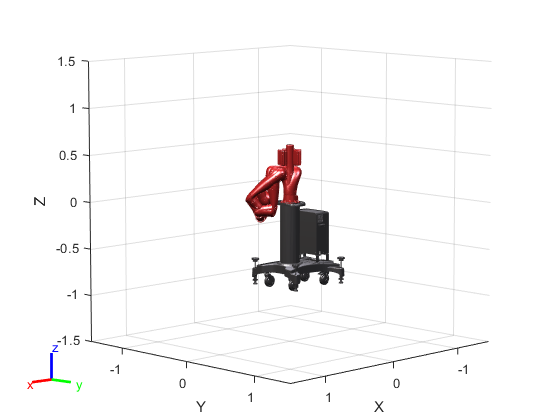

robot = importrobot('sawyer.urdf', DataFormat='column');

for i = 1:width(solutions)

    q_i = solutions(:,i);
    show(robot, [q_i(1); 0; q_i(2:end)], "Frames","off");
    %show(robot, [q_i(1); 0; q_i(2:end)], "Visuals","off");
    if i == 1
        hold on
    end
    
end
hold off
light('Position', [1 0 1], 'Color',  0.75*[1 0.9 0.9])
light('Position', [0 1 1], 'Color',  [0.9 0.9 1])
light('Position', [-1 -1 1], 'Color', 0.5*[0.9 0.9 1])

function n = vec_normalize(vec)
    n =  vec / norm(vec);
end